The Lokta-Volterra model can be modified to use logistic growth, to add a limited carrying capacity to the prey population. The resulting equations become


$$\frac{dx_1}{dt}=a x_1\left(1-\frac{x_1}{K}\right) - b x_1x_2 \\ \frac{dx_2}{dt}=c x_1 x_2 - d x_2 $$


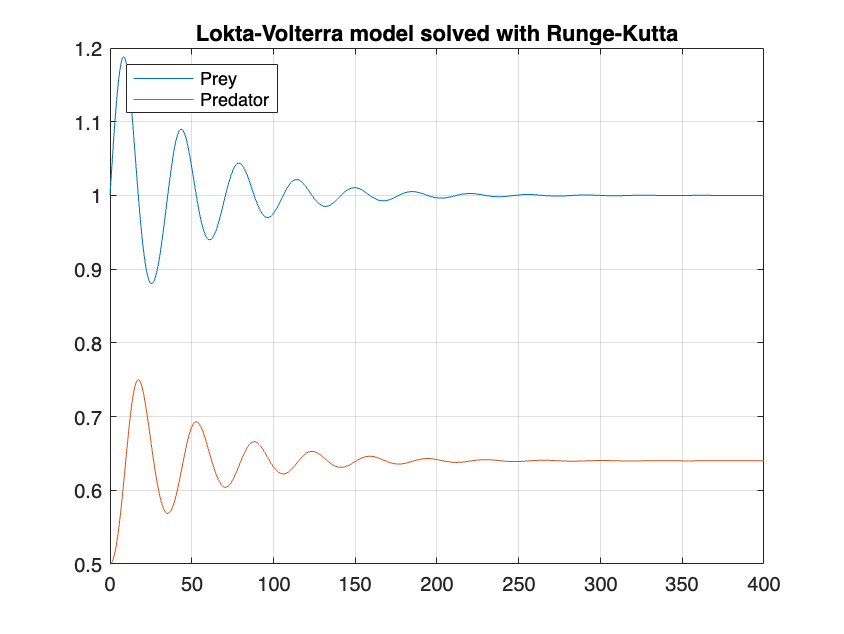

a = 0.2; b = 0.25; c = 0.2; d = 0.2; K = 5;
prey = 1; predator = 0.5; n = 1000;

f = Logistic(a,b,c,d,K);

[x,t] = RungeKutta(f, 0, 400, [prey; predator], n);
plot(x,t)
grid
legend("Prey","Predator",location="northwest")
title("Lokta-Volterra model solved with Runge-Kutta")

When a carrying capacity is added into the system, the model will generally converge into a stable population.